clc
clear
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\pixel_videos_directioned_Iqtau\';
% filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\wavelength_Analysis\';
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

wavelength=31*0.15*sqrt(2);
scale=1024;
q_max=200;
plotIq_all_dirc_all_tau(angle_Iqtau,path,wavelength,scale,q_max)

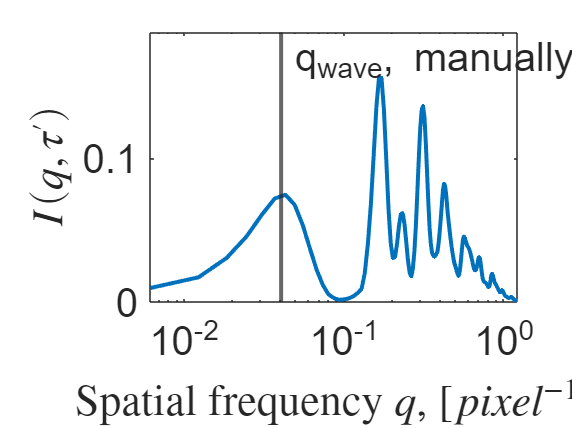

tau=16;
wavenumber=31*0.15*sqrt(2);
scale=1024;
q_max=200;
fps=10;
%     load(filename);
%     angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
%     q_num=size(angle_Iqtau,2);
%     tVec=1:size(angle_Iqtau,3);
%     t_num=size(angle_Iqtau,3);
fig=figure();
y=sum(angle_Iqtau(:,1:q_max,tau),1);
smooth_y = smoothdata(squeeze(y), 'gaussian', 12);

%% for circle model videos
lambda=32;
semilogx(qVec(1:q_max)*2*pi/scale,smooth_y,"LineWidth",2)
hxl = xline(wavenumber*2*pi/scale,'-',{'q_{wave}, manually'},'LabelOrientation','horizontal','LineWidth',2);
hxl.FontSize = 20;
%     hxl_g.FontSize=20;
%     ylim([0 1.2*max(y_avg)]);
ylim([0 1.2*max(smooth_y)]);
%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 20); 
xlabel('Spatial frequency $q$, [$pixel^{-1}$]','Interpreter','latex')
% ylabel(['$I(q,\tau''=' num2str(round(tau/fps,2)) 's)$'],'Interpreter','latex')
ylabel(['$I(q,\tau'')$'],'Interpreter','latex')
xticks([10^(-2) 10^(-1) 10^(0)])

filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat';
input=[path filename];
load(input);

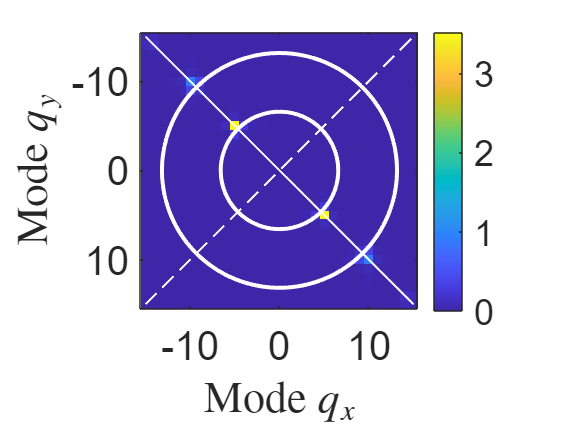

theta=0;
wavenumber=31/(1/0.15)*sqrt(2);
scale=1024;
q_range=15;
tau=8;
radius=scale/2+1;
theta = pi/4;
fig=figure();

a=fftshift(nonAvgIqtau(:,:,tau));
a(radius,radius)=0;
%     a=a';
a(radius,radius,tau)=0;
imagesc(a(radius-q_range:radius+q_range,radius-q_range:radius+q_range), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
hold on;

x = -q_range:0.1:q_range;
y = x*tan(-theta);
z = x/tan(theta);
plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
hold on;
viscircles([0,0],wavenumber,'Color',[1,1,1,0.2],'LineStyle','-','LineWidth',1);
viscircles([0,0],wavenumber*2,'Color',[1,1,1,0.2],'LineStyle','-','LineWidth',1);

set(gca,'dataAspectRatio',[1 1 1])
colorbar;
xlabel('Mode $q_x$','Interpreter','latex');
ylabel('Mode $q_y$','Interpreter','latex');
set(gca,'fontsize', 20);


path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\time_freq_Analysis\';
data1=load([path 'large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat']);% Tile 1
data2=load([path 'large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat']);% Tile 1
data3=load([path 'large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.6_gray_nonAvgIqtau_angle_Iqtau.mat']);% Tile 1

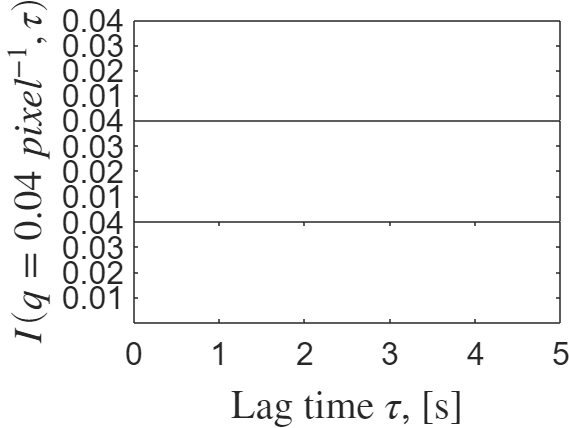

clf;
q=7;
scale=1024;
figure()
t = tiledlayout(3,1,'TileSpacing','none','Padding','none');

nexttile;

plot(tVec/10,squeeze(sum(data1.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 

% ylim([0 0.05])

nexttile; % Tile 2

plot(tVec/10,squeeze(sum(data2.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 


nexttile;
plot(tVec/10,squeeze(sum(data3.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 


set(t.Children,'XTick',[]); % all in one
set(t.Children,'YTick',[0.01 0.02 0.03 0.04]); % all in one
xticks(gca,[0 1 2 3 4 5]);
xlim([0 5])

xlabel(t,'Lag time $\tau$, [s]','Interpreter','latex','FontSize',20)
ylabel(t,['$I(q=$' num2str(round(q*2*pi/scale,2)) ' $pixel^{-1},\tau)$'],'Interpreter','latex','FontSize',20)

% title(t,'I(q=6,tau)-tau plot for different time frequencies','FontSize',16);
% xlabel(t,'lag time tau(s)','FontSize',16);
% ylabel(t,'I(q=6,tau)','FontSize',16);

clf
t=10;
q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,1:q_max,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau(:,10:100,:),2),3)));
xticks(1:angle_num)
xlabel('direction *pi/8')
ylabel('sum of Iqtau')
% ylim([0.00 1])
title('Sum of I(q=1:100,tau) in 8 directions')

figure()
q_max=120;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,:),1)));
xticks([50 100 150])
xticklabels({'5','10','15'})
xlabel('lag time tau(s)')
ylabel('wavenumber q')
title('I(q,tau) heatmap')
colorbar;
set(gca,'fontsize', 12);

figure()
q=27;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

x=tVec/30/5;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
exclude=[1 2];
% FT = fittype('x./210000 + k.*x.^n')
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.05, 0.01, -0.05, 4], 'Exclude', exclude)
h=plot( f, x, y ,"o") 
h(1).LineWidth=2;
h(2).LineWidth=2;
title(['I(q=' num2str(q) ',tau)-tau plot'])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
legend('data','fit')
set(gca,'fontsize', 16);

q=3;
x=tVec/30/5;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
exclude=[1 2];
% FT = fittype('x./210000 + k.*x.^n')
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.05, 0.01, -0.05, 4], 'Exclude', exclude)
h=plot( f, x, y ,"o") 
h(1).LineWidth=2;
h(2).LineWidth=2;
title(['I(q=' num2str(q) ',tau)-tau plot'])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
legend('data','fit')
set(gca,'fontsize', 16);

coeffnames(ft)

figure()
subplot(3,1,1);
q=10;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q'',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,2);
q=20;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,3);
q=30;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

q=3;
figure();
bar(1:angle_num,squeeze(sum(angle_Iqtau(:,q,:),3)));
xticks((1:angle_num)-1)
xlabel('Direction *\pi/16','Interpreter','tex')
ylabel('Sum of I(q,\tau)','Interpreter','tex')
% title(['Sum of Iqtau(q=' num2str(q) ') in 16 directions'])
set(gca,'fontsize', 20);

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\wavelength_Analysis\';
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat';
input=[path filename];
load(input)

wavenumber=0;
scale=1024;
q_range=15;
tau=8;
theta=0;
clf;
plotFFTdifference(nonAvgIqtau,theta,wavenumber,scale,q_range,tau,path)

    
radius=scale/2+1;
fig=figure();

a=fftshift(nonAvgIqtau(:,:,tau));
a(radius,radius)=0;
%     a=a';
a(radius,radius,tau)=0;
imagesc(a(radius-q_range:radius+q_range,radius-q_range:radius+q_range), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
hold on;

x = -q_range:0.1:q_range;
y = x*tan(-theta);
z = x/tan(theta);
plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
hold on;
viscircles([0,0],wavenumber,'Color',[1,1,1,0.2],'LineStyle','-','LineWidth',3);
% text(x(end),y(end),'perpendicular');
set(gca,'dataAspectRatio',[1 1 1])
colorbar;
xlabel('Mode $q_x$','Interpreter','latex');
ylabel('Mode $q_y$','Interpreter','latex');
set(gca,'fontsize', 20);

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\wavelength_Analysis\';
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat';
input=[path filename];
wavenumber=0;
scale=1024;
q_range=100;
tau=16;
theta=0;
plotFFTdifference(input,theta,wavenumber,scale,q_range,tau,path)

% x_label=(0:angle_num-1)*180/angle_num
% strsplit(num2str(round(x_label)))
% set(gca,'xticklabel',{'40 feet','60 feet','120 feet'})

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau,2),3)));

figure()
plot(1:t_num,squeeze(angle_Iqtau(1,1,:)))

imagesc(log(squeeze(sum(angle_Iqtau(5,1:10,:),1))))

% filename='large_fx_0.02_fy_0.02_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0202=load(input);
% 
% filename='large_fx_0.02_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0210=load(input);
% 
% filename='large_fx_0.02_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0200=load(input);

% filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0000=load(input);

q_max=50;
figure()
z=sum(angle_Iqtau(1:16,(1:q_max),:),1);
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(z))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Sum of all directions')

num_of_wave_on_diagonal=1.41;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)


path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\plots\'

clc
filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=6;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.2_fy_0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=12;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=8.5;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.05_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=23;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
% filename='large_theta_-2.618(rad)_fx_-0.1_fy_-0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
filename='large_theta_-3.1416(rad)_fx_-2.45e-17_fy_-0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat'
load(filename);
num_of_wave_on_diagonal=8;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

q_max=100;
figure()
y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3)...
    -sum(sum(angle_Iqtau0000.angle_Iqtau(1:16,(1:q_max),:),1),3);
plot(qVec(1:q_max),squeeze(y))
% xlim([0 200])
xlabel('q')
ylabel('Iqtau')
title('Sum of all directions, all taus')

figure()
t=30;
q_max_to_include=3;
q=17; % peak ]
subplot(4,1,1)
plot(1:angle_num,sum(angle_Iqtau0200.angle_Iqtau(:,1:q_max_to_include,t),2))
xlabel('direction')
ylabel('I(q=17,t=16)')
title('f_x=0.02, f_y=0')
subplot(4,1,2)
plot(1:angle_num,sum(angle_Iqtau0202.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.02')
subplot(4,1,3)
plot(1:angle_num,sum(angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.05')
subplot(4,1,4)
plot(1:angle_num,sum(angle_Iqtau0210.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.10')
sgtitle('I in 16 different directions')

d=15;
q=2;
tVec=1:50;
fig=figure();
subplot(3,1,1)
plot(tVec/10,squeeze(angle_Iqtau02.angle_Iqtau(d,q,:)))
title('f_t=0.2Hz')
ylabel('I(q=2,t)')
subplot(3,1,2)
plot(tVec/10,squeeze(angle_Iqtau(d,q,:)))
title('f_t=0.4Hz')
ylabel('I(q=2,t)')
subplot(3,1,3)
plot(tVec/10,squeeze(angle_Iqtau06.angle_Iqtau(d,q,:)))
title('f_t=0.6Hz')
xlabel('time (s)')
ylabel('I(q=2,t)')
sgtitle('I(q=2,t)-t plot for different time frequencies')

saveas(fig,'I(q=2,t)-t plot for different time frequencies.png')


filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau02=load(input);

filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.6_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau06=load(input);

surf(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 1')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(2,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 2')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(3,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 3')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(4,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 4')

plot(1:50,squeeze(angle_Iqtau(1,30,:)))

scale=846;
plot3(repmat((1-scale/2:scale/2)',1,scale),repmat((1-scale/2:scale/2),scale,1),fftshift(squeeze(nonAvgIqtau(:,:,10))))
xlabel('q_x')
ylabel('q_y')
zlabel('FFT difference')
title('FFT difference at tau=10s')

q=7;
f=figure();
clf
t = tiledlayout(3,1,'TileSpacing','none','Padding','none');

nexttile;

plot(tVec/10,squeeze(sum(data1.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 

% ylim([0 0.05])

nexttile; % Tile 2

plot(tVec/10,squeeze(sum(data2.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 


nexttile;
plot(tVec/10,squeeze(sum(data3.angle_Iqtau(:,q,:),1)),'LineWidth',1.5)
set(gca,'fontsize', 16); 

set(t.Children,'XTick',[]); % all in one
set(t.Children,'YTick',[0.01 0.02 0.03 0.04]); % all in one

title(t,'I(q=6,tau)-tau plot for different time frequencies','FontSize',16);
xlabel(t,'lag time tau(s)','FontSize',16);
ylabel(t,'I(q=6,tau)','FontSize',16);
set(gca,'fontsize', 16); 
